# ELEC-8103 – Modelling, Estimation, and Dynamic Systems

# Assignment 1 

# Deadline: **17.09.2023 at 23:59**

# **1. Problem1 (5 points)**

Consider the mass-spring-damper system depicted in Fig. 1 below.

- The coefficients for the mass, spring, and damper are represented by $m$, $k$, and $b$, respectively.

- The positions of the masses are denoted by $q_1$ and $q_2$.

- In this system, we are interested in the position of mass $q_2$.

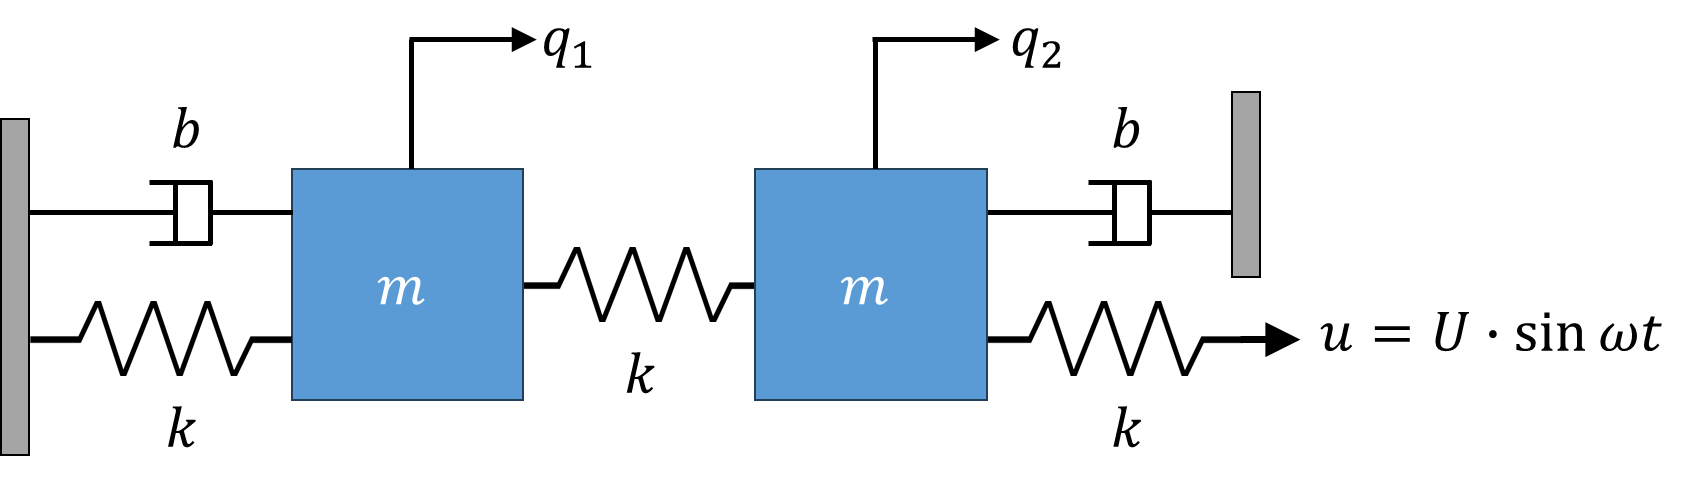

**Figure 1** – Mass-spring-damper system.

#### **a) Answer the following **questions**: (0.5 points) **

- **What signal(s) are the output(s) of the system?**

- **What signal(s) are the input(s) of the system?**

- **What are the constants of the system?**

- **What are the internal time-varying variables of the system?**

%---------------------------------------------------------------
%                       Your Answer Below
%---------------------------------------------------------------

% Input signal(s):u

% Output signal(s):q2

% Constants:k,b,m

% Internal time-varying variables:q1,q2 and the velocity of the masses.

#### b) Establish the fundamental equations for the system. You are expected to derive the differential equations governing the system's motion using first principles. (1.5 points)

# 
$$\textrm{Type}\;\textrm{Equations}\;\textrm{here}$$



$$\begin{array}{l}
\textrm{Eq}\ldotp 1{\;F}_1 =m\overset{\cdot \cdot }{q_1 } \\
\textrm{Eq}\ldotp 2{\;F}_2 =m\overset{\cdot \cdot }{q_2 } \\
\textrm{Eq}\ldotp 3\;m\overset{\cdot \cdot }{q_1 } =-b\overset{\cdot }{q_1 } -kq_1 -k\left(q_1 -q_2 \right)\\
\textrm{Eq}\ldotp 4\;m\overset{\cdot \cdot }{q_2 } =-b\overset{\cdot }{q_2 } -k\left(q_2 -q_1 \right)-k\left(q_2 -u\right)
\end{array}$$


#### c) Construct the state-space representation of the system:

- **Begin by selecting the state variables.**

- **Next, express the equations of motion (derived in part “1-b”) in state-space format. **

####  (0.5 points)

# 
$$\textrm{Type}\;\textrm{Equations}\;\textrm{here}$$



$$\begin{array}{l}
\textrm{Eq}\ldotp 1\;x_1 =q_1 \;,x_2 =\overset{\cdot }{q_1 } ,\;x_3 =q_2 ,{\;x}_4 =\overset{\cdot }{q_2 } \\
\textrm{Eq}\ldotp 2\;\;\overset{\cdot }{x} =\left\lbrack \begin{array}{c}
x_2 \\
-\frac{2\cdot k}{m}\cdot x_1 -\frac{b}{m}\cdot x_2 +\frac{k}{m}\cdot x_3 \\
x_4 \\
\frac{k}{m}\cdot x_1 -\frac{2\cdot k}{m}\cdot x_3 -\frac{b}{m}\cdot x_4 +\frac{k}{m}\cdot u
\end{array}\right\rbrack \\
\textrm{Eq}\ldotp 3\;y=\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 0 & 1 & 0
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_4 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x_1 \\
x_3 
\end{array}\right\rbrack 
\end{array}$$


#### d) Create a script below. Within this script: 

- **Assume the system parameter values given in the code below.**

- **Construct the state-space equations for the system.**

- **Compute the system's transfer function.**

#### **(1 point)**

#### **Hint****: Use functions **[**ss**](https://se.mathworks.com/help/control/ref/ss.html?s_tid=doc_ta)** and **[**ss2tf**](https://se.mathworks.com/help/matlab/ref/ss2tf.html)**. **

% System parameters:
m = 250; % (kg) mass
k = 50; % (N/m) spring stiffness
b = 50; % (N*s/m) damping coefficient
U = 0.01; % (m) amplitude
w = 1; % (rad/s) angular frequency

%---------------------------------------------------------------
% State-space representation:
A = [0 1 0 0; -2*k/m -b/m k/m 0; 0 0 0 1; k/m 0 -2*k/m -b/m];
B = [0; 0; 0; k/m];
C = [1 0 0 0; 0 0 1 0];
D = [0; 0];

sys = ss(A, B, C, D);

% Transfer function:

TF_system =
 
          0.2 s^2 + 0.04 s + 0.08
  ----------------------------------------
  s^4 + 0.4 s^3 + 0.84 s^2 + 0.16 s + 0.12
 
连续时间传递函数。
模型属性


[num, den] = ss2tf(A, B, C, D);
TF_system = tf(num(2,:),den);
TF_system
%---------------------------------------------------------------

#### e) Assume that all initial state values are zero. Compute and plot the position of mass $q_2$ in response to an input $u=U\cdot \sin \left(\omega t\right)$ over a duration of 40 seconds. **Assume the system parameter values given in the code above**. 

#### Hint: Use function [lsim](https://se.mathworks.com/help/ident/ref/dynamicsystem.lsim.html). (0.5 points)

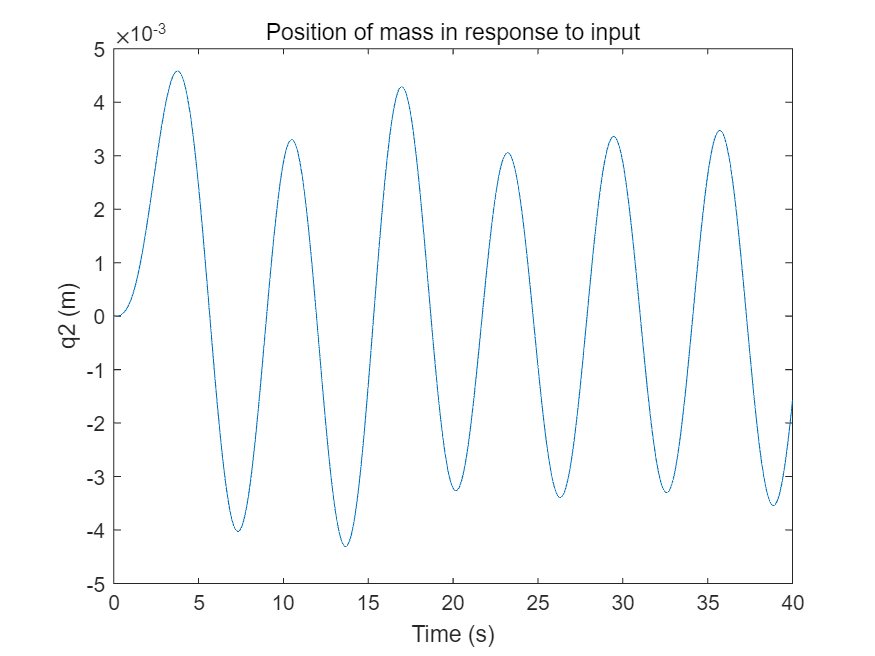

%---------------------------------------------------------------
t = 0:0.01:40;

% input
u = U*sin(w*t);

% system response
[y, t] = lsim(sys,u,t);

% Draw quality position response
subplot;
plot(t,y(:,2));
xlabel('Time (s)');

ylabel('q2 (m)');
title('Position of mass in response to input');
%---------------------------------------------------------------

#### f) Vary the input frequency ($\omega$) from 2 rad/s to 5 rad/s in increments of 1 rad/s and plot the resulting motion of mass $q_2$ on a single figure over the 40-second span. Based on the figure, how does the frequency influence the steady-state amplitude of the motion? (1 point)

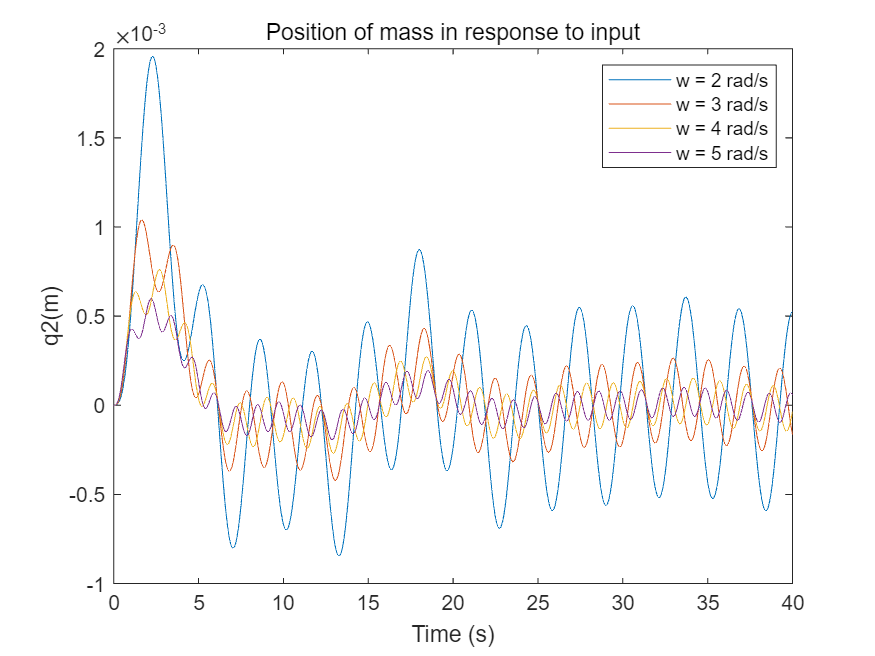

%---------------------------------------------------------------
for w = 2:1:5 % use for loop to calculate

    % input signal
    u = U*sin(w*t);

    % system response
    y = lsim(sys,u,t);

    % Draw quality position response
    plot(t,y(:,2), 'DisplayName', sprintf('w = %d rad/s', w));
    hold on;
end

xlabel('Time (s)');
ylabel('q2(m)');
title('Position of mass in response to input');
legend;

hold off;
%---------------------------------------------------------------
%---------------------------------------------------------------
%From the figure we can find that as the frequnency increases, the amplitude becomes smaller.
%---------------------------------------------------------------

# **2. Problem 2 (5 points)**

Consider a chemical reactor represented in Fig. 2. The reactor converts a reactant into a product and consists of:

- **A reaction tank: **Within this tank, the chemical reaction occurs. It has the following parameters: volume $V$, homogeneous temperature $T$, concentration of the reactant $A\left(t\right)$ (mol/L), and concentration of the product$B\left(t\right)$ (mol/L).

- **Inflow channel: **This channel allows the reactant to flow into the tank. Within this channel, concentration of the reactant is denoted as $A_{\textrm{in}} \left(t\right)$ (mol/L), and volumetric flow rate is represented by $q_{\textrm{in}}$ (L/s).

- **Outflow channel: **Through this channel, both the product and the reactant are discharged from the tank. The volumetric flow rate for this channel is represented by $q_{\textrm{out}}$ (L/s).

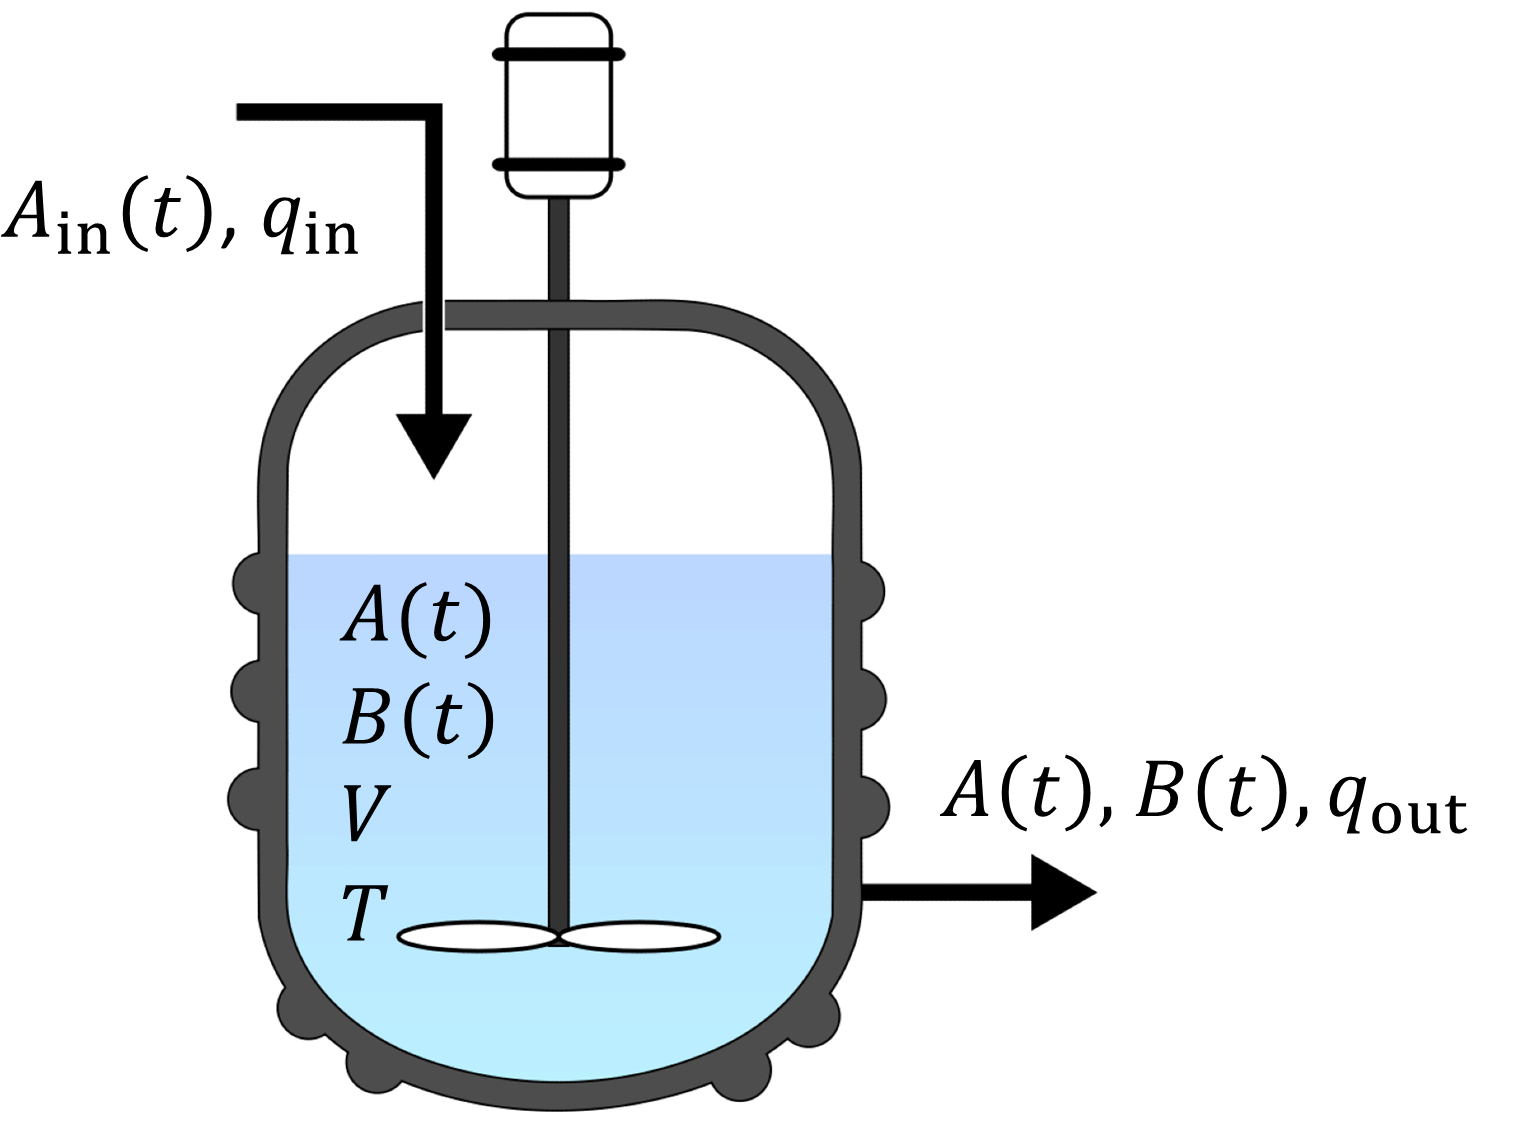

**Figure 2** – Chemical reactor.

- Within the tank, the reactant ($A$) is converted into the product ($B$) based on the rate,

# $r=k\cdot A\left(t\right)$,

             where $r$ represents the reaction rate in mol/(s∙L), and $k$ is the rate constant defined by the Arrhenius equation as follows,

# 
$$k=k_0 \cdot e^{-\frac{E}{R\cdot T}}$$


             Here, $k_0$ is the frequency of collisions resulting in the reaction, $R$ is the gas constant, and $E$ is the activation energy for the reaction (see [here](https://en.wikipedia.org/wiki/Arrhenius_equation) for more details).

- We are interested in how $A_{\textrm{in}}$ influences the concentrations of the reactant and product in the tank, i.e., $A\left(t\right)$ and $B\left(t\right)$.

#### **a) Answer the following questions: (0.5 points)**

- **What signal(s) are the output(s) of the system?**

- **What signal(s) are the input(s) of the system?**

- **What are the constants of the system?**

- **What are the internal time-varying variables of the system?**

%---------------------------------------------------------------
%                       Your Answer Below
%---------------------------------------------------------------

% Input signal(s):A_in(t)
% Output signal(s):A(t),B(t)
% Constants:V,T,q_in,q_out
% Internal time-varying variables:A(T),B(T)

#### b) Derive the differential equations for the system using first principles. These equations will depict the temporal evolution of the concentrations of the reactant and product within the reaction tank. (1.5 points)

**Hints****:** 

**    (1)** Use the general mole balance equation:

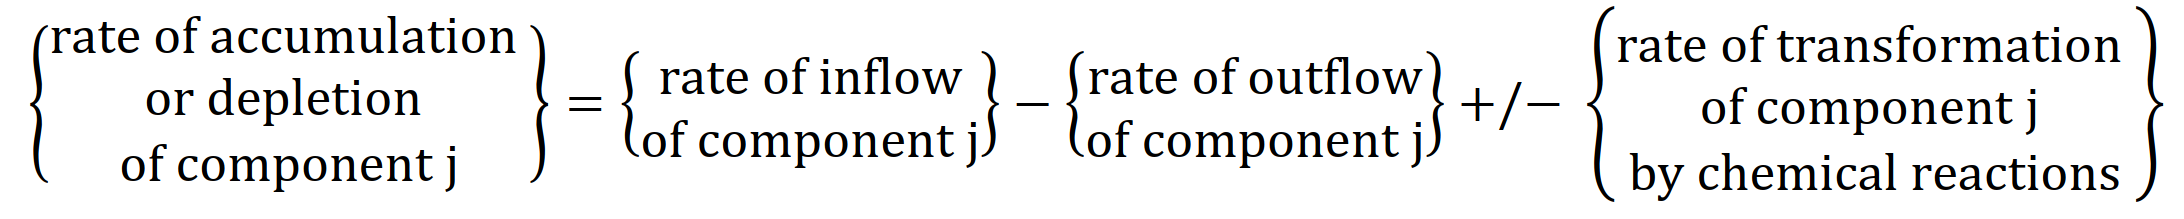

**﻿    (2)** Make sure that the units (mol/s) of both sides of the equations match.

# 
$$\textrm{Type}\;\textrm{Equations}\;\textrm{here}$$



$$\begin{array}{l}
\textrm{Eq}\ldotp 1\;\overset{\cdot }{A\left(t\right)} =\frac{q_{\textrm{in}} }{V}{\cdot A}_{\textrm{in}} \left(t\right)-k\cdot A\left(t\right)-\frac{q_{\textrm{out}} }{V}\cdot A\left(t\right)\\
\textrm{Eq}\ldotp 2\;\overset{\cdot }{B\left(t\right)} =k\cdot A\left(t\right)-\frac{q_{\textrm{out}} }{V}\cdot B\left(t\right)
\end{array}$$


#### **c) Construct the state-space representation of the system. (1 point)**

# 
$$\textrm{Type}\;\textrm{Equations}\;\textrm{here}$$



$$\begin{array}{l}
\textrm{Eq}\ldotp 1\;x_1 =A\left(t\right)\\
\textrm{Eq}\ldotp 2\;x_2 =B\left(t\right)\\
\textrm{Eq}\ldotp 3\;\overset{\cdot }{x} =\left\lbrack \begin{array}{c}
-\left(\frac{q_{\textrm{out}} }{V}+k\right)\cdot x_1 +\frac{q_{\textrm{in}} }{V}\cdot A_{\textrm{in}} \left(t\right)\\
k\cdot x_1 -\frac{q_{\textrm{out}} }{V}\cdot x_2 
\end{array}\right\rbrack \\
\textrm{Eq}\ldotp 4\;y=\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack 
\end{array}$$


#### **d) Create a script below. Within the script: **

- **Assume the system parameters have the values given in the code below.**

- **Construct the state-space equations for the system.**

- **Assume that the reactant concentration in the inflow channel is given by (in mol/L):**

#  
$$A_{\textrm{in}} \left(t\right)=\frac{1}{0\ldotp 3\sqrt{\pi }}e^{-{\left(\frac{t}{0\ldotp 3}\right)}^2 }$$


- **Calculate and plot the concentrations of the reactant and product in the tank, i.e., **$A\left(t\right)$** and **$B\left(t\right)$**, over a duration of 20 seconds.**

**Hint****: Use functions **[**ss**](https://se.mathworks.com/help/control/ref/ss.html?s_tid=doc_ta)** and **[**lsim**](https://se.mathworks.com/help/ident/ref/dynamicsystem.lsim.html)**. (1.5 points)**

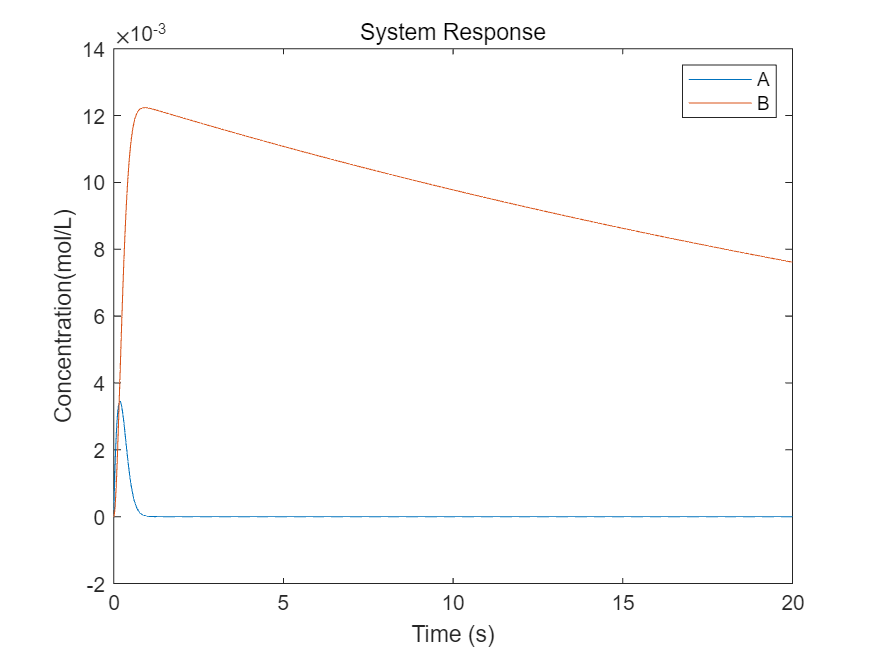


% System parameters:
V = 10; % (L) volume of the tank
q_in = 0.25; % (L/s) inflow rate
q_out = 0.25; % (L/s) outflow rate
E = 2500; % (J/mol) activation energy
R = 8.31; % (J/mol*K) gas constant
k_0 = 9.4; % (1/s) frequency of collisions
T = 293; % (K) temperature

%---------------------------------------------------------------
A = [-q_out/V-k_0 0; k_0 -q_out/V];
B = [q_in/V; 0];
C = [1 0; 0 1];
D = [0; 0];

sys = ss(A, B, C, D);
t = 0:0.01:20;
A_in = (1/(0.3*sqrt(pi))) * exp(-(t/0.3).^2); 
y = lsim(sys,A_in,t);
plot(t,y(:,1));
hold on;
plot(t,y(:,2));
title('System Response');
xlabel('Time (s)');

ylabel('Concentration(mol/L)');
legend('A', 'B');
hold off;
%---------------------------------------------------------------


#### e) By simulating the system, answer the following questions. 

- **At what time does the concentration of the reactant in the tank, 𝐴(𝑡), become negligible?**

- **At what time does the concentration of the product in the tank, 𝐵(𝑡), become negligible?**

#### An approximate time will suffice. (0.5 points)

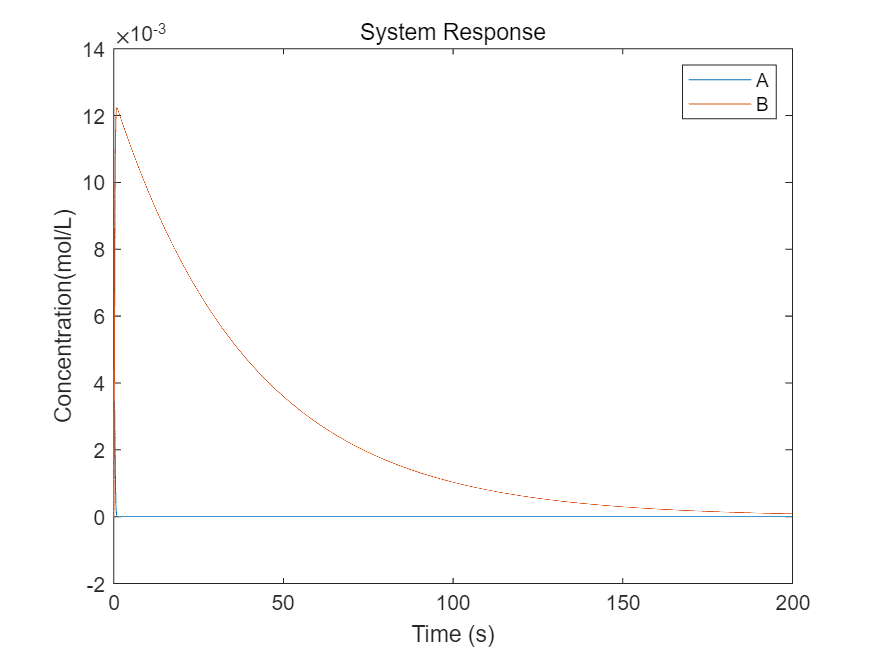

%---------------------------------------------------------------
t = 0:0.01:200;
A_in = (1/(0.3*sqrt(pi))) * exp(-(t/0.3).^2); 
y = lsim(sys,A_in,t);
plot(t,y(:,1));
hold on;
plot(t,y(:,2));
title('System Response');
xlabel('Time (s)');

ylabel('Concentration(mol/L)');
legend('A', 'B');
hold off;
%---------------------------------------------------------------

%---------------------------------------------------------------
% From the plotted graph, it can be observed that A(t) becomes negligible around t = 1s and B(t) becomes negligible around t = 170s.
%---------------------------------------------------------------

# **What to return?**

You are expected to submit your assignment to the related link for Assignment 1 in MyCourses.

Your submission should include one completed .mlx file, “**Assignment_1_*your_student_number*.mlx**”.

# **The hard deadline for submission of this assignment is 17.09.2023 at 23:59.**